# RX Anomaly detection on all the spectra

## First we concatenate all the different Spectra measures


image = cat(3,Reflection,Transmission,Scom);

## We try calculating the scores on the whole image

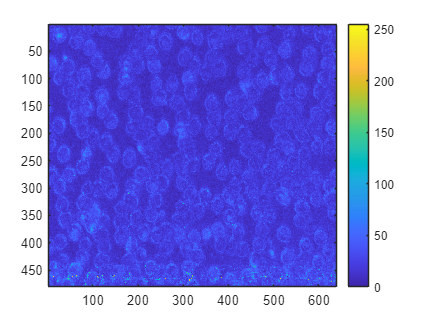

regionPixels = find(labelscyto > 0);
W = image;
for i = (1:39)
    W(:,:,i) = wiener2(W(:,:,i),[5 5]);
end
rxScoresprep = anomalyRX(W); %scores with denoising
rxScores = anomalyRX(image); %scores without denoising
rxScores = im2uint8(rescale(rxScores));
rxScoresprep = im2uint8(rescale(rxScoresprep));
%% values are in general very low so we want to remove the few pixels that
%% have very high values to try to see anomalous cells light up
extremes = 80;
rxScores(rxScores>extremes) = 0;
rxScoresprep(rxScoresprep>extremes) = 0;
rxScores = im2uint8(rescale(rxScores));
rxScoresprep = im2uint8(rescale(rxScoresprep));


imagesc(rxScores)
colorbar

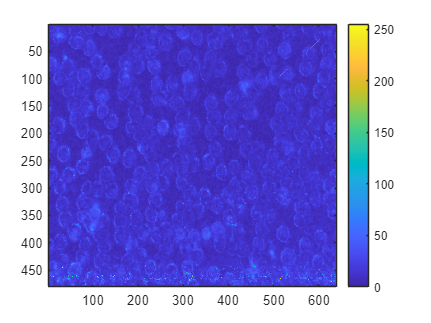

imagesc(rxScoresprep)
colorbar

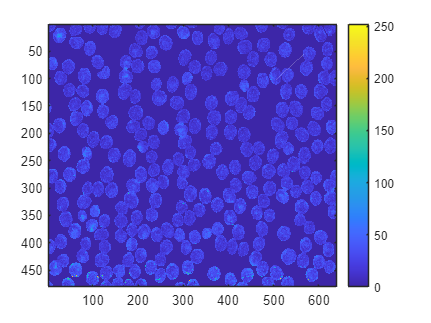


masked = rxScores;
masked(labelscyto == 0) = 0;
maskedp = rxScoresprep;
maskedp(labelscyto == 0) = 0;
imagesc(masked)
colorbar

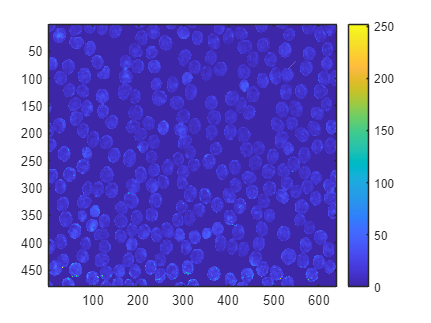

imagesc(maskedp)
colorbar

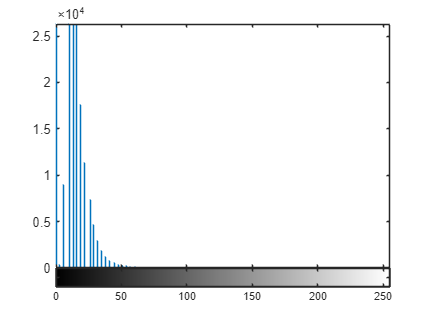

imhist(maskedp)

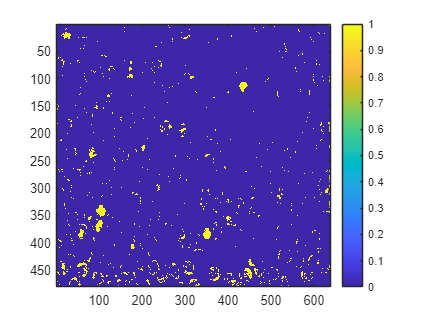

thresh= maskedp > 30; % we proceed with the denoised image
imagesc(thresh)
colorbar

## Now we try to automate candidate selection

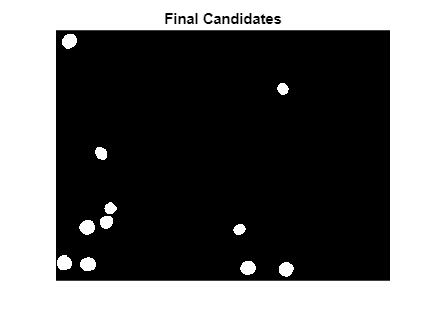


numLabels = max(labelscyto(:));

% Initialize a mask to hold the selected labels
selectedMask = zeros(size(labelscyto));

% Loop through each label
for label = 1:numLabels
    % Get a binary mask for the current label
    labelMask = (labelscyto == label);
    
    % Count the total number of pixels in this label
    totalPixels = sum(labelMask(:));
    
    % Count the number of anomalous pixels in this label
    numAnomalous = sum(thresh(labelMask));
    
    % Calculate the percentage of anomalous pixels in this label
    anomalyPercentage = (numAnomalous / totalPixels) * 100;
    
    % If the anomaly percentage exceeds the threshold, keep this label
    if numAnomalous > 165
        selectedMask(labelMask) = label;
    end
end
imshow(selectedMask);
title('Final Candidates');

## Now we try to minimimize background pixels when calculating rxScore


[X, Y, Bands] = size(image);

% Get the total number of labels in the segmentation mask
numLabels = max(labelscyto(:));

% Cap MaxPixelsPerLabel at 800 (observed maximum amount of pixels per cell)
MaxPixelsPerLabel = min(800, ceil((X * Y) / numLabels));


spectraMatrix = zeros(numLabels, MaxPixelsPerLabel, Bands);

% Loop through each label
for label = 1:numLabels
    % Get a binary mask for the current label
    labelMask = (labelscyto == label);
    
    % Find the indices of the pixels in this label
    [row, col] = find(labelMask);
    
    % Limit the number of pixels to MaxPixelsPerLabel
    numPixels = min(length(row), MaxPixelsPerLabel);
    row = row(1:numPixels);
    col = col(1:numPixels);
    
    % Extract the spectra of these pixels
    pixelSpectra = zeros(numPixels, Bands); 
    for i = 1:numPixels
        % Get the spectra for each pixel using row, col indices
        pixelSpectra(i, :) = W(row(i), col(i), :);
    end
    
    spectraMatrix(label, 1:numPixels, :) = pixelSpectra;
end


disp(size(spectraMatrix));% each row represents a different cell

   266   800    39



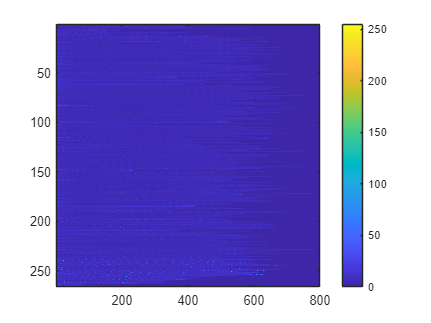

rxScores = anomalyRX(spectraMatrix);

rxScores = im2uint8(rescale(rxScores));
imagesc(rxScores)
colorbar

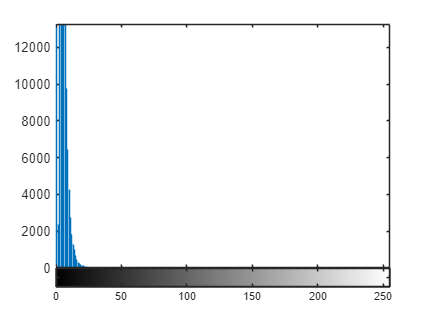


imhist(rxScores) %trying to find good threshold to discard extremes

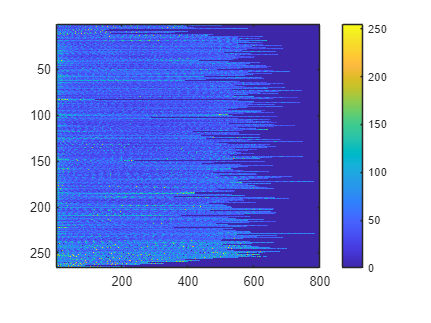


extremes = 30;
rxScores(rxScores>extremes) = 0;
rxScores = im2uint8(rescale(rxScores));
imagesc(rxScores)
colorbar

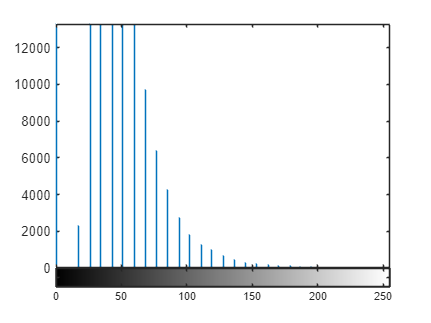

imhist(rxScores) %trying to find good threshold to discard extremes

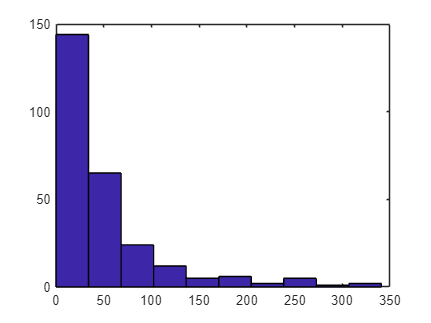

thresh = rxScores>80;

%Calculate the anomaly score of every cell
threshs = sum(thresh,2);
hist(threshs)

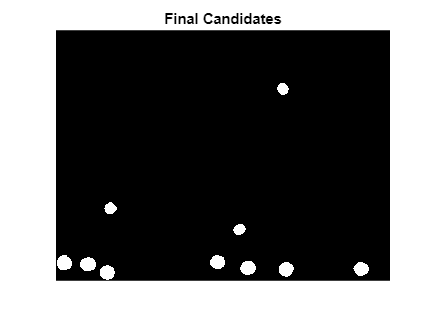


selectedMask = zeros(size(labelscyto));
%Loop through every score and discard below the threshold
for label = 1:numLabels
    labelMask = (labelscyto == label);
    if threshs(label) > 200
        selectedMask(labelMask) = label;
    end
end
imshow(selectedMask);%noisy cells very favored
title('Final Candidates');